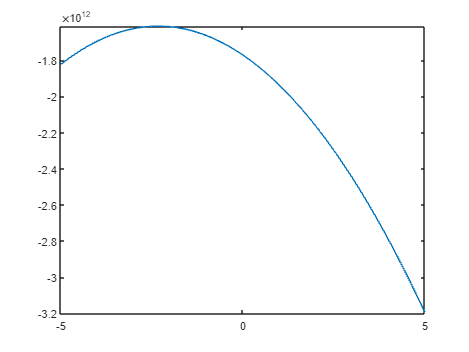

clc
clear
A = [25 5 1 ;64 8 1;144 12 1];
B = [106.8 177.2 279.2];
answer = jacobi(A,B,20);
n = length(B);
syms t V(t);
V(t) = 0;
for i = 1 : n
    V(t) = V(t) + answer(i)*t^(n-i);
end
V2 = vpa(V(10));
fplot (V(t));

function output = jacobi(A,B,iteration)
n = length(B);
x = zeros(n,1);
x_new = zeros(n,1);
for i = 1 : iteration
    for j = 1 : n
        x_new(j) = (B(j)-A(j,[1:j-1,j+1:n])*x([1:j-1,j+1:n],1))/A(j,j);
    end
    x = x_new;
end
output = x_new;
end
